# Convert Arrays to Cell - num2cell

Place all elements of a numeric array into separate cells. 

a = magic(3)

a =      8     1     6
     3     5     7
     4     9     2


c = num2cell(a)

c = 3×3 cell 배열
    {[8]}    {[1]}    {[6]}
    {[3]}    {[5]}    {[7]}
    {[4]}    {[9]}    {[2]}


Place individual letters of a word into separate cells of an array. 

a = ['four';'five';'nine']

a = 3×4 char 배열
    'four'
    'five'
    'nine'


c = num2cell(a)

c = 3×4 cell 배열
    {'f'}    {'o'}    {'u'}    {'r'}
    {'f'}    {'i'}    {'v'}    {'e'}
    {'n'}    {'i'}    {'n'}    {'e'}


iscell(c)

ans = logical
   1


# Convert Cell to Array - cell2mat

Convert cell array to ordinary array of the underlying data type

`A = cell2mat(`[`C`](https://www.mathworks.com/help/matlab/ref/cell2mat.html#bufa81t-C)`)` converts a cell array into an ordinary array. The elements of the cell array must all contain the same data type, and the resulting array is of that data type.

The contents of `C` must support concatenation into an N-dimensional rectangle. Otherwise, the results are undefined. For example, the contents of cells in the same column must have the same number of columns, although they need not have the same number of rows (see figure).

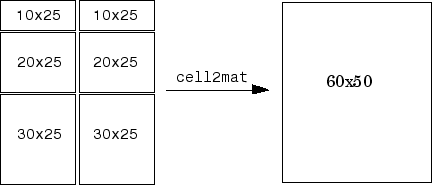

C = {[1],    [2 3 4];
     [5; 9], [6 7 8; 10 11 12]}

C = 2×2 cell 배열
    {[       1]}    {1×3 double}
    {2×1 double}    {2×3 double}


A = cell2mat(C)

A =      1     2     3     4
     5     6     7     8
     9    10    11    12


whos A

  Name      Size            Bytes  Class     Attributes

  A         3x4                96  double              



# Convert between numbers and character array - num2str & str2num

[`s`](https://www.mathworks.com/help/matlab/ref/num2str.html?searchHighlight=num2str&s_tid=srchtitle#btfaj9t-1-s) `=` `num2str``(`[`A`](https://www.mathworks.com/help/matlab/ref/num2str.html?searchHighlight=num2str&s_tid=srchtitle#btfaj9t-1-A)`)` converts a numeric array into a character array that represents the numbers. The output format depends on the magnitudes of the original values. `num2str` is useful for labeling and titling plots with numeric values.

Convert the floating-point values returned by `pi` and `eps` to character vectors.

s = num2str(pi)

s = '3.1416'

s = num2str(eps)

s = '2.2204e-16'

[`X`](https://www.mathworks.com/help/matlab/ref/str2num.html?searchHighlight=num2str&s_tid=srchtitle#d123e1284543) `= str2num(`[`chr`](https://www.mathworks.com/help/matlab/ref/str2num.html?searchHighlight=num2str&s_tid=srchtitle#d123e1284458)`)` converts a character array or string scalar to a numeric matrix. The input can include spaces, commas, and semicolons to indicate separate elements. If `str2num` cannot parse the input as numeric values, then it returns an empty matrix.

Convert character vectors that represent numbers.

X = str2num('100 200 300 400')

X =    100   200   300   400


Convert a character vector containing `true` and `false` to a logical array.

X = str2num('false true true false')

X = 1×4 logical 배열
   0   1   1   0


[`str`](https://www.mathworks.com/help/matlab/ref/string.html?searchHighlight=string&s_tid=srchtitle#d123e1288684) `=` `string``(`[`A`](https://www.mathworks.com/help/matlab/ref/string.html?searchHighlight=string&s_tid=srchtitle#d123e1288354)`)` converts the input array to a string array. 

A = [1 20 300];
X = string(A)

X = 1×3 string 배열
    "1"    "20"    "300"


# Convert Array and Select Data by Category

Create a categorical array that has weather station labels. Add it to a table of temperature readings. Then use the categories to select temperature readings by station.

First, create arrays containing temperature readings, dates, and station labels.

Temps = [58; 72; 56; 90; 76];
Dates = {'2017-04-17';'2017-04-18';'2017-04-30';'2017-05-01';'2017-04-27'};
Stations = {'S1';'S2';'S1';'S3';'S2'};

Convert `Stations` to a categorical array.

Stations = categorical(Stations)

Stations = 5×1 categorical 배열
     S1 
     S2 
     S1 
     S3 
     S2 


Display the categories. The three stations labels are categories.

categories(Stations)

ans = 3×1 cell 배열
    {'S1'}
    {'S2'}
    {'S3'}


Create a table that contains the temperatures, dates, and station labels.

T = table(Temps,Dates,Stations)

T = 5×3 table
    Temps        Dates         Stations
    _____    ______________    ________

     58      {'2017-04-17'}       S1   
     72      {'2017-04-18'}       S2   
     56      {'2017-04-30'}       S1   
     90      {'2017-05-01'}       S3   
     76      {'2017-04-27'}       S2   


Display the readings taken from station `S2`. You can use the `==` operator to find the values of `Station` that equal `S2`. Then use logical indexing to select the table rows that have data from station `S2`.

TF = (T.Stations == 'S2');
T(TF,:)

ans = 2×3 table
    Temps        Dates         Stations
    _____    ______________    ________

     72      {'2017-04-18'}       S2   
     76      {'2017-04-27'}       S2   


# Convert Table to Cell Array

Create a table, `T`, with five rows and three variables. 

sex = categorical({'M';'M';'F';'F';'F'})

sex = 5×1 categorical 배열
     M 
     M 
     F 
     F 
     F 


age = [38;43;38;40;49]

age =     38
    43
    38
    40
    49


bp = [124 93;109 77; 125 83; 117 75; 122 80]

bp =    124    93
   109    77
   125    83
   117    75
   122    80


T = table(sex, age, bp,...
    'VariableNames',{'Gender' 'Age' 'BloodPressure'},...
    'RowNames',{'Smith' 'Johnson' 'Williams' 'Jones' 'Brown'})

T = 5×3 table
                Gender    Age    BloodPressure
                ______    ___    _____________

    Smith         M       38      124     93  
    Johnson       M       43      109     77  
    Williams      F       38      125     83  
    Jones         F       40      117     75  
    Brown         F       49      122     80  


Convert `T` to a cell array. 

C = table2cell(T)

C = 5×3 cell 배열
    {[M]}    {[38]}    {1×2 double}
    {[M]}    {[43]}    {1×2 double}
    {[F]}    {[38]}    {1×2 double}
    {[F]}    {[40]}    {1×2 double}
    {[F]}    {[49]}    {1×2 double}


`C` is a 5-by-3 cell array. 

Vertically concatenate the table property, `T.Properties.VariableNames`, with `C` to include column headings for the cell array. 

[T.Properties.VariableNames;C]

ans = 6×3 cell 배열
    {'Gender'}    {'Age'}    {'BloodPressure'}
    {[M     ]}    {[ 38]}    {1×2 double     }
    {[M     ]}    {[ 43]}    {1×2 double     }
    {[F     ]}    {[ 38]}    {1×2 double     }
    {[F     ]}    {[ 40]}    {1×2 double     }
    {[F     ]}    {[ 49]}    {1×2 double     }


`T.Properties.VariableNames` is a cell array of character vectors. 

# Convert Structure to Cell Array

Create a structure.

S.x = linspace(0,2*pi);     % Generate linearly spaced vector
S.y = sin(S.x);
S.title = 'y = sin(x)'

S = 다음 필드를 포함한 struct :
        x: [1×100 double]
        y: [1×100 double]
    title: 'y = sin(x)'


isstruct(S)

ans = logical
   1


Convert `S` to a cell array.

C = struct2cell(S)

C = 3×1 cell 배열
    {1×100 double}
    {1×100 double}
    {'y = sin(x)'}
